## Mesh processing toolbox

### Author & support : nicolas.douillet (at) free.fr, 2020-2021.

### Example #1 : vertex normals

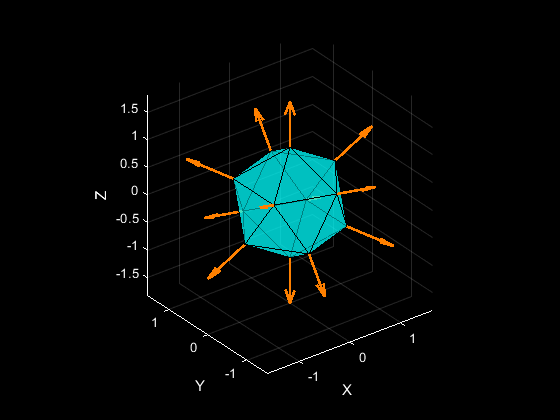

Mesh with 12 vertices and 20 triangles displayed in 2.004168e-01 seconds.


addpath('data/');
addpath('src/');

load('icosahedron.mat');
ngb_degre = 1;
select_vertex_normals(V,T,ngb_degre);

### Example #2 : non manifold triangles

load('kitten_nmnfld.mat');
nmnfld_tgl_idx_list = select_non_manifold_triangles(V,T);

Mesh with 5224 vertices and 10911 triangles displayed in 1.002704e-01 seconds.


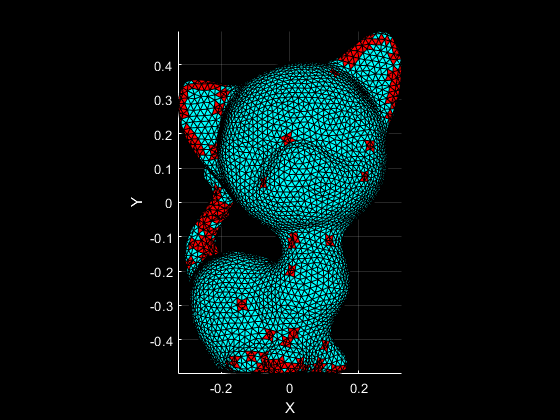

view(0,90);

### Example #3 : connected components

load('kitten_components.mat');
[cc_nb,components] = segment_connected_components(T);

4 components found in 1.430861e+00 seconds.


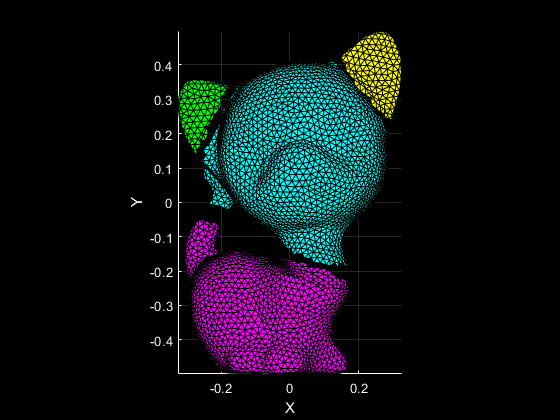

show_mesh_components(V,components);
view(0,90);

### Example #4 : holes and boundary selection

load('kitten_holed.mat');
nmnfld_vtx_idx = select_non_manifold_vertices(V,T,false);
[V,T] = clone_solve_nmnfld_vertices(V,T,nmnfld_vtx_idx);

1 components found in 1.896300e-03 seconds.
1 components found in 1.728000e-04 seconds.
1 components found in 1.468000e-04 seconds.
1 components found in 2.878400e-03 seconds.
2 components found in 1.440100e-03 seconds.
duplicate_nmnfld_vertices request executed in 4.516050e-02 seconds. 5 clone vertices added.


boundaries = select_holes_and_boundary(V,T);

6 boundaries detected in 6.344040e-02 seconds.


Mesh with 5120 vertices and 10115 triangles displayed in 7.536760e-02 seconds.


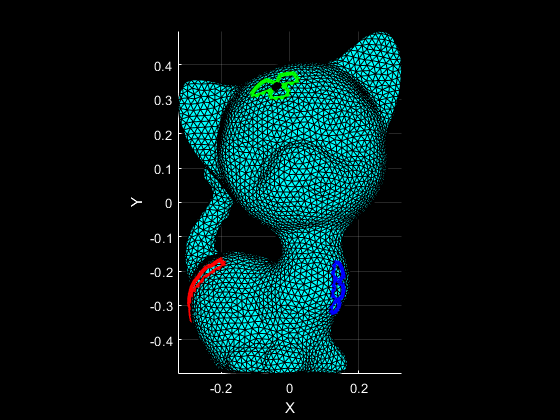

view(0,90);

### Example #5 : hole filling

[V,T] = remove_non_manifold_vertices(V,T);

0 non manifold vertices removed in 9.328530e-01 seconds.


boundaries = select_holes_and_boundary(V,T);

6 boundaries detected in 6.139820e-02 seconds.


Mesh with 5120 vertices and 10115 triangles displayed in 8.754530e-02 seconds.


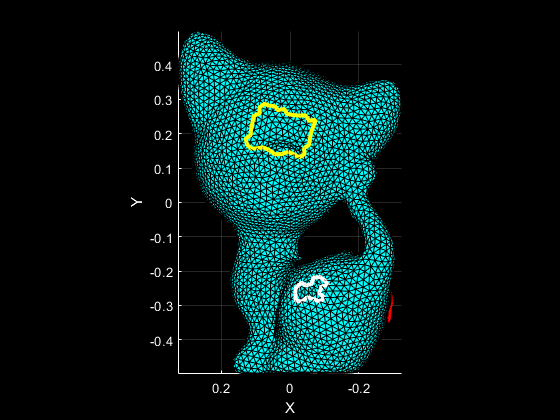

view(-180,-90);


max_perim_sz = 200;
T = fill_mesh_holes(V,T,boundaries,'closed',max_perim_sz);

6 hole(s) filled by adding 121 triangles in 4.969010e-01 seconds.


plot_mesh(V,T);

Mesh with 5120 vertices and 10236 triangles displayed in 7.567780e-02 seconds.


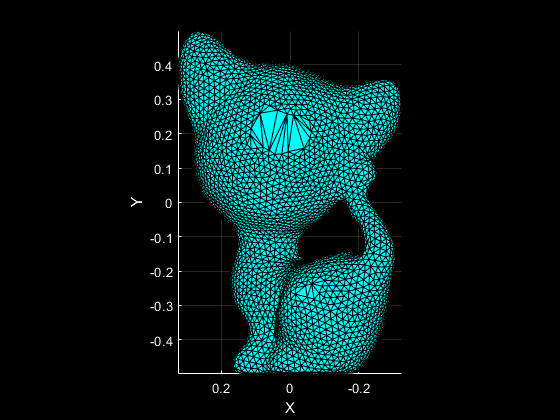

view(-180,-90);

### Example #6 : curvature

load('kitten.mat');
ngb_degre = 2;
N = compute_vertex_normals(V,T,ngb_degre,'raw');
curvature = compute_mesh_curvature(V,T,N,ngb_degre,'mean');

mean curvature computed in 7.072173e-01 seconds.


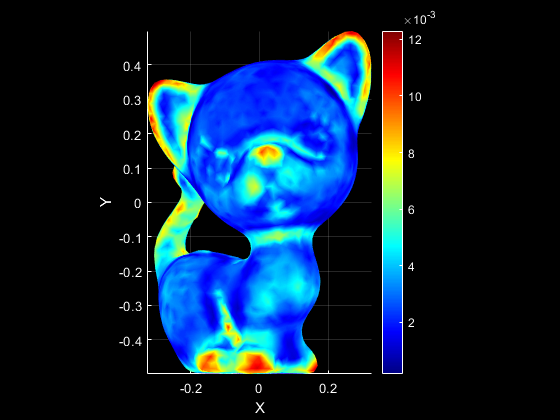

show_mesh_curvature(V,T,curvature);
view(0,90);

### Example #7 : subselection

load('Gargoyle_3k.mat');
plot_mesh(V,T);

Mesh with 1429 vertices and 2836 triangles displayed in 7.356270e-02 seconds.


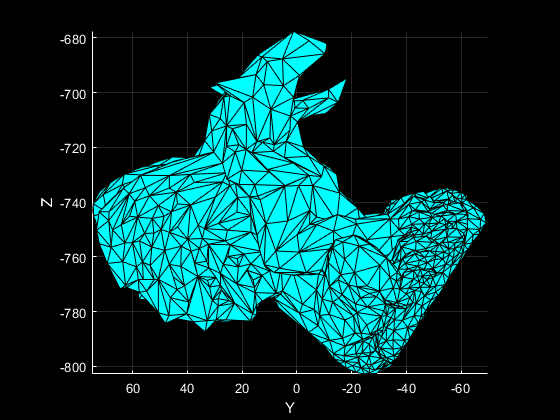

view(-90,0);


n = [0 1 0];
I = [0 -25 800];
[V_out,T_out] = submesh_selection(V,T,n,I); % Gargoyle top part 

submesh with 729 vertices and 4221 triangles selected in 1.853770e-02 seconds.



plot_mesh(V_out,T_out);

Mesh with 726 vertices and 4221 triangles displayed in 7.117540e-02 seconds.


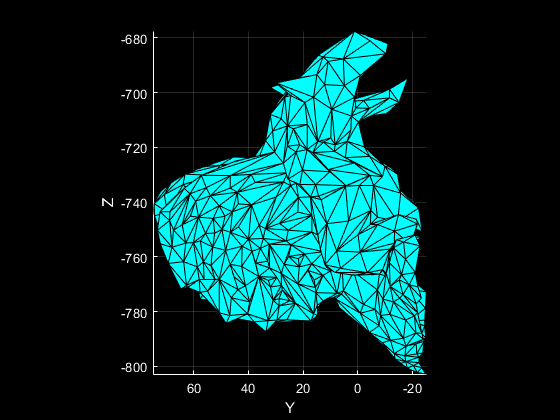

view(-90,0);

### Example #8 : smoothing

plot_mesh(V,T), shading interp, camlight right;

Mesh with 1429 vertices and 2836 triangles displayed in 7.070410e-02 seconds.


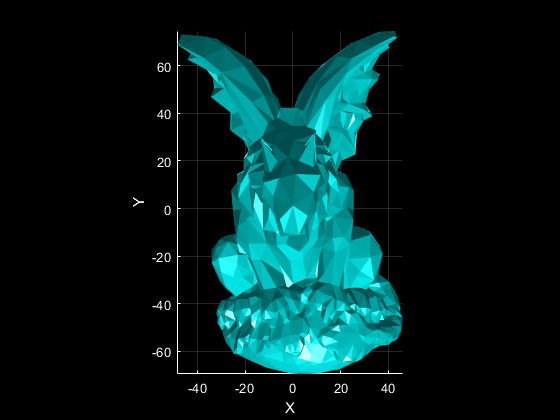

view(0,90);


N = compute_vertex_normals(V,T,2);
nb_iterations = 1;
ngb_degre = 1;
V = mesh_smooth(V,T,nb_iterations,ngb_degre);

Laplacian mesh smoothed in 6.057270e-02 seconds.



plot_mesh(V,T), shading interp, camlight right;

Mesh with 1429 vertices and 2836 triangles displayed in 6.840050e-02 seconds.


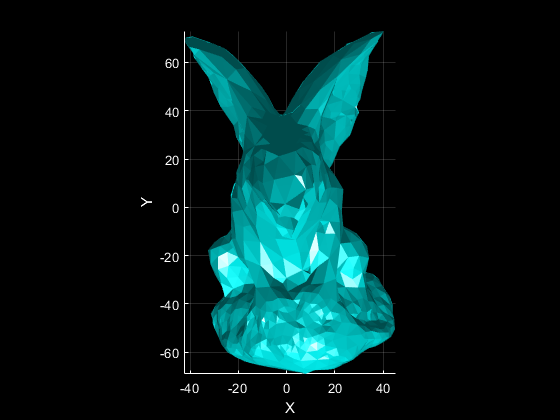

view(0,90);

### Example #9 : convex hull

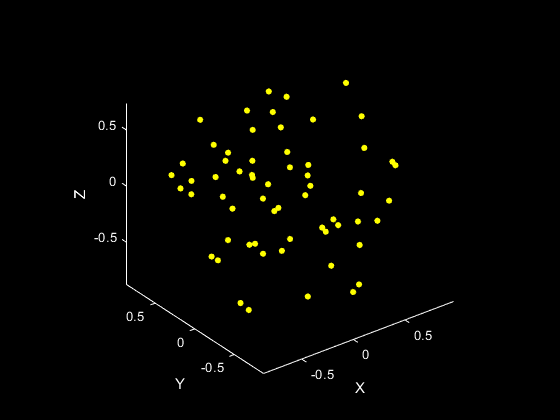

nb_vtx = 128;
X = 2*(rand(nb_vtx,1)-0.5);
Y = 2*(rand(nb_vtx,1)-0.5);
Z = 2*(rand(nb_vtx,1)-0.5);

Rho = X.^2 + Y.^2 + Z.^2;
i = Rho <= 1;
X = X(i);
Y = Y(i);
Z = Z(i);
V = cat(2,X,Y,Z);

plot_point_set(V,'o','y',4);
axis equal;
view(3);


[V,Qh] = quick_hull(V);

Mesh quick hull computed in 3.906769e-01s.


plot_mesh(V,Qh);

Mesh with 30 vertices and 56 triangles displayed in 6.916150e-02 seconds.


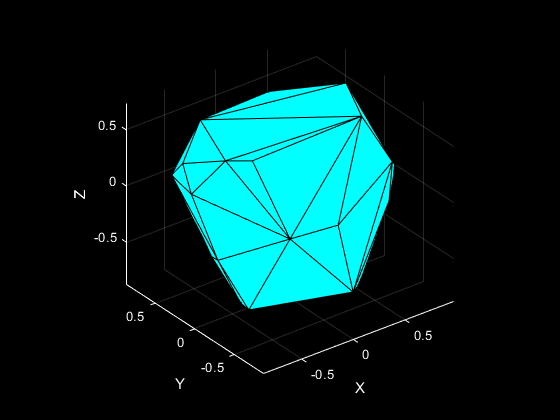

axis equal;
view(3);

### Example #10 : boundary smoothing

load('kitten_components.mat');

show_holes_and_boundary(V,T);

Mesh with 4975 vertices and 9669 triangles displayed in 8.495340e-02 seconds.


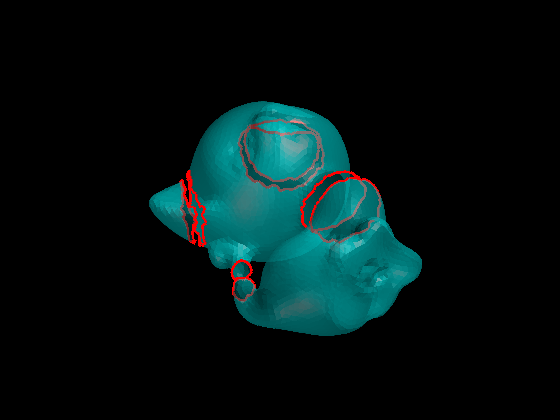

shading interp;
camlight right;
alpha(0.5);
view(3);
axis off;


boundaries = detect_mesh_holes_and_boundary(T);

8 boundaries detected in 5.720840e-02 seconds.



nb_iterations = 2;
ngb_degre = 6;
V_out = smooth_mesh_boundaries(V,boundaries,nb_iterations,ngb_degre);

Mesh boundaries smoothed in 5.253800e-03 seconds.



show_holes_and_boundary(V_out,T);

Mesh with 4975 vertices and 9669 triangles displayed in 7.178130e-02 seconds.


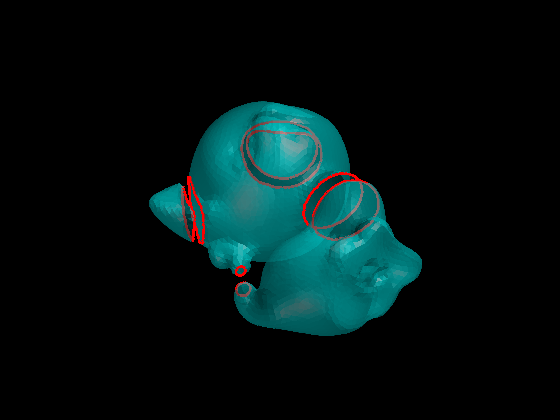

shading interp;
camlight right;
alpha(0.5);
view(3);
axis off;